Distort an image `img` based on probability parameter `p` by adding impulse noise according to a noise model $I_{noisy}$.

Author: Arjun Bawa, Last modified on Dec 4, 2021

The noise model $I_{noisy}$ is given by


$$\[
I_{noisy}(i,j) = 
\begin{cases}
    I(i,j) & & x \geq p \\
    (I_r(i,j), I_g(i,j), z) & y \lt {1 \over 3} & x \lt p \\
    (I_r(i,j), z, I_b(i,j)) & {1 \over 3} \leq y \lt {2 \over 3} & x \lt p \\
    (z, I_g(i,j), I_b(i,j)) & {2 \over 3} \leq y & x \lt p \\
\end{cases}
\]$$



$$I := \text{original image} \\
I_r, I_g, I_b := \text{red, green, blue components of original image} \\
x,y \in [0,1] , \ z \in [0,255]:= \text{uniform random values} \\ 
p \in [0,1] := \text{parameter describing probability of noise in image}$$


Naively, the above can be implemented by iterating through each pixel $I(i,j)$ in `img` and computing a new pixel $I_{noisy}(i,j)$ for the resulting distorted image. However, leveraging vectorized matrix operations can make this computation much more efficient. 

function distorted_img = distort(img, p)
    x = rand(size(img, 1:2));
    y = rand(size(img, 1:2));
    z = randi(256, size(img)) - 1;
    
    r1 = uint8(repmat(x >= p, [1,1,3]));
    r2 = uint8(repmat((x < p & y < 1/3), [1,1,3]));
    r3 = uint8(repmat((x < p & y >= 1/3 & y < 2/3), [1,1,3]));
    r4 = uint8(repmat((x < p & y >= 2/3), [1,1,3]));
    
    img_rg = img;
    img_rb = img;
    img_gb = img;
    
    img_rg(:,:,3) = z(:,:,3);
    img_rb(:,:,2) = z(:,:,2);
    img_gb(:,:,1) = z(:,:,1);
    
    distorted_img = (img .* r1) + (img_rg .* r2) + (img_rb .* r3) + (img_gb .* r4);
end

The series of diagrams below explain the above computation, considering each step individually before combining them. First, some notation is as follows. $X$ and $Y$ are also defined as matrix representations of the $x$ and $y$ from $I_{noisy}$.

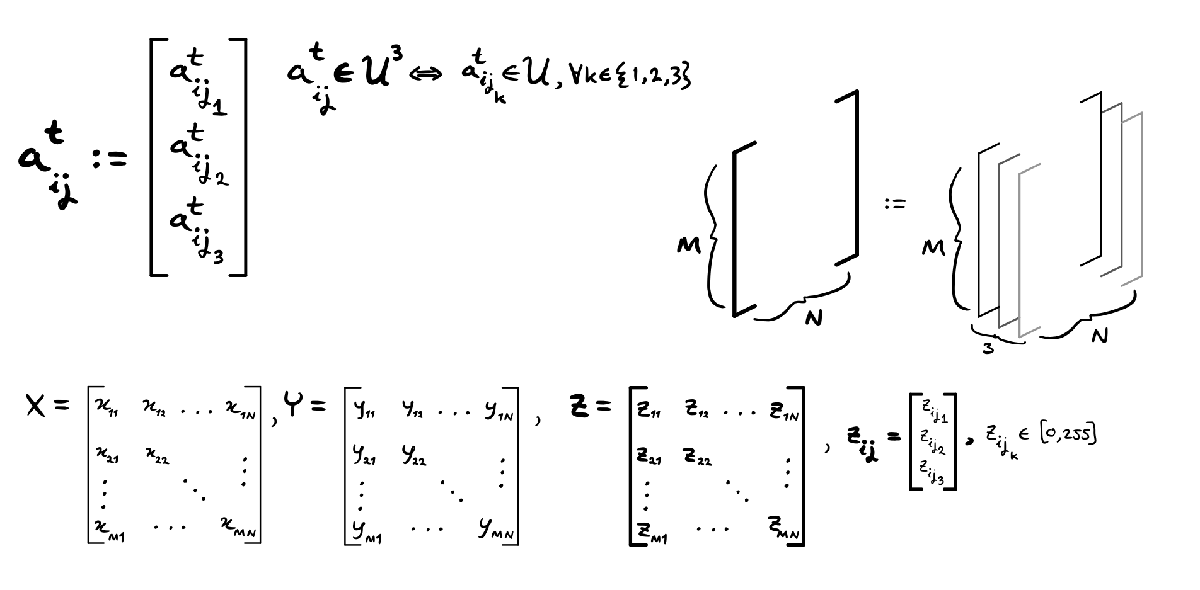

`r1`, `r2`, `r3`, `r4` in the funtion's code above are bit-masks created in the following ways.

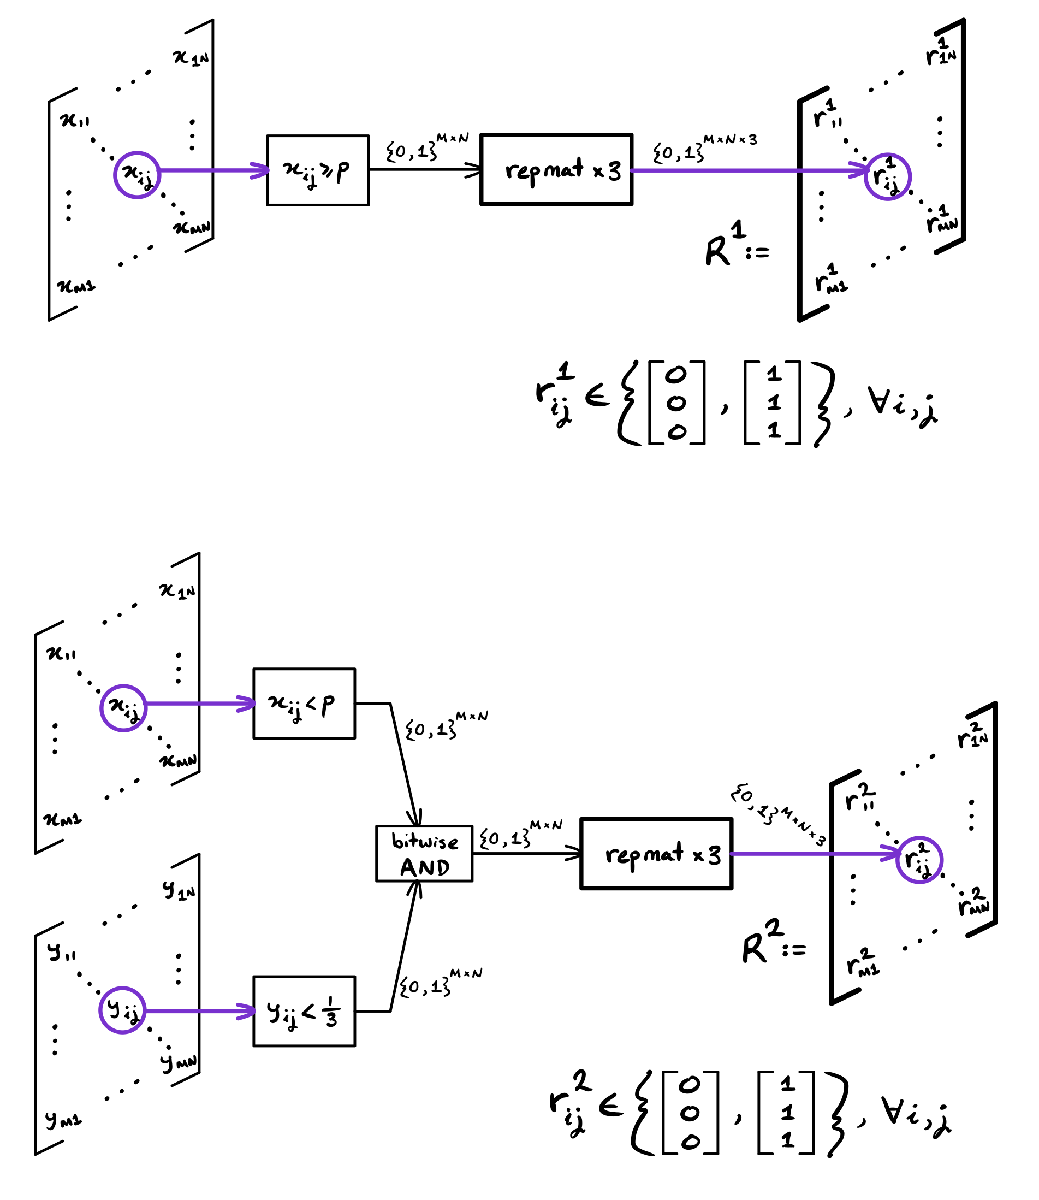

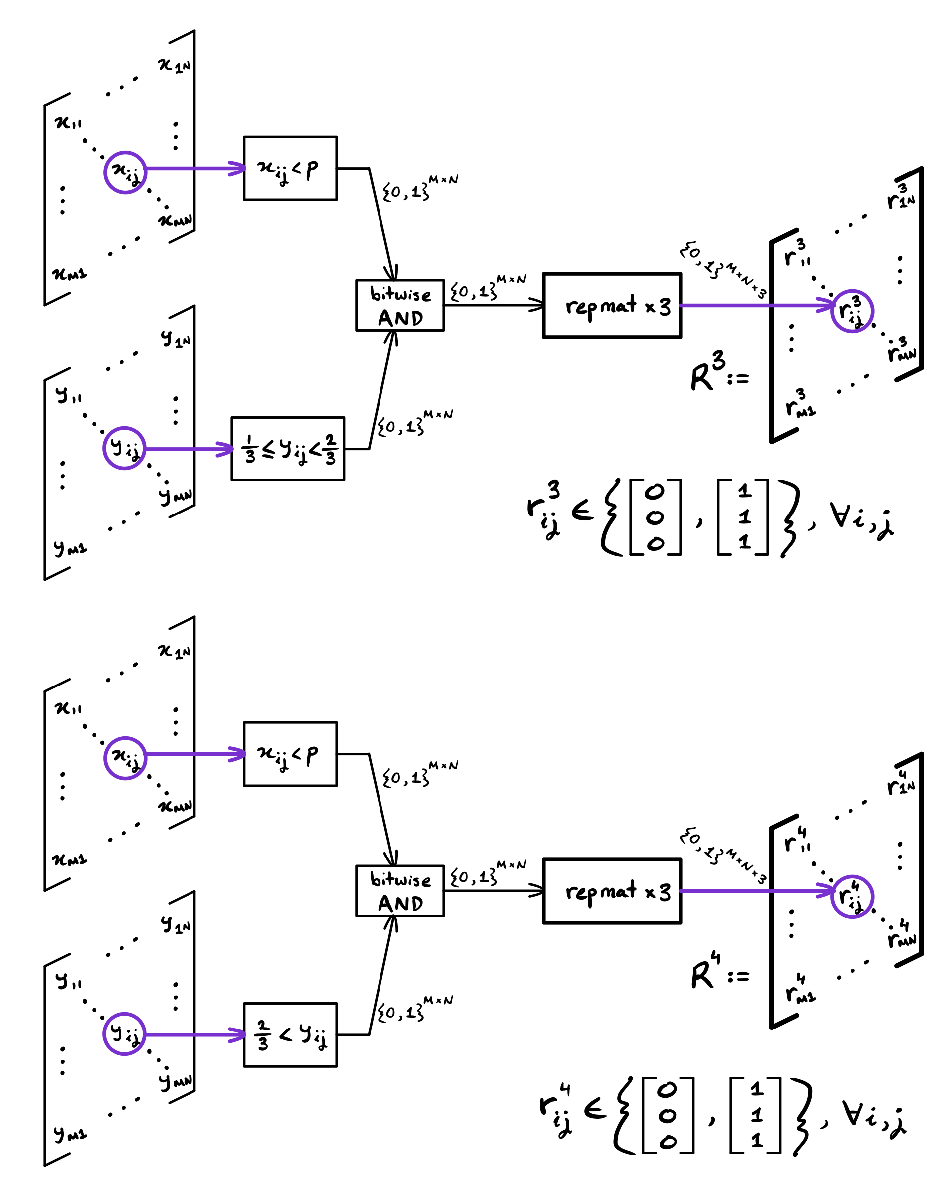

`r1`, `r2`, `r3`, `r4` in the funtion's code above are created such that `r1 + r2 + r3 + r4` yields a matrix of `1`s with dimension `size(img)`.

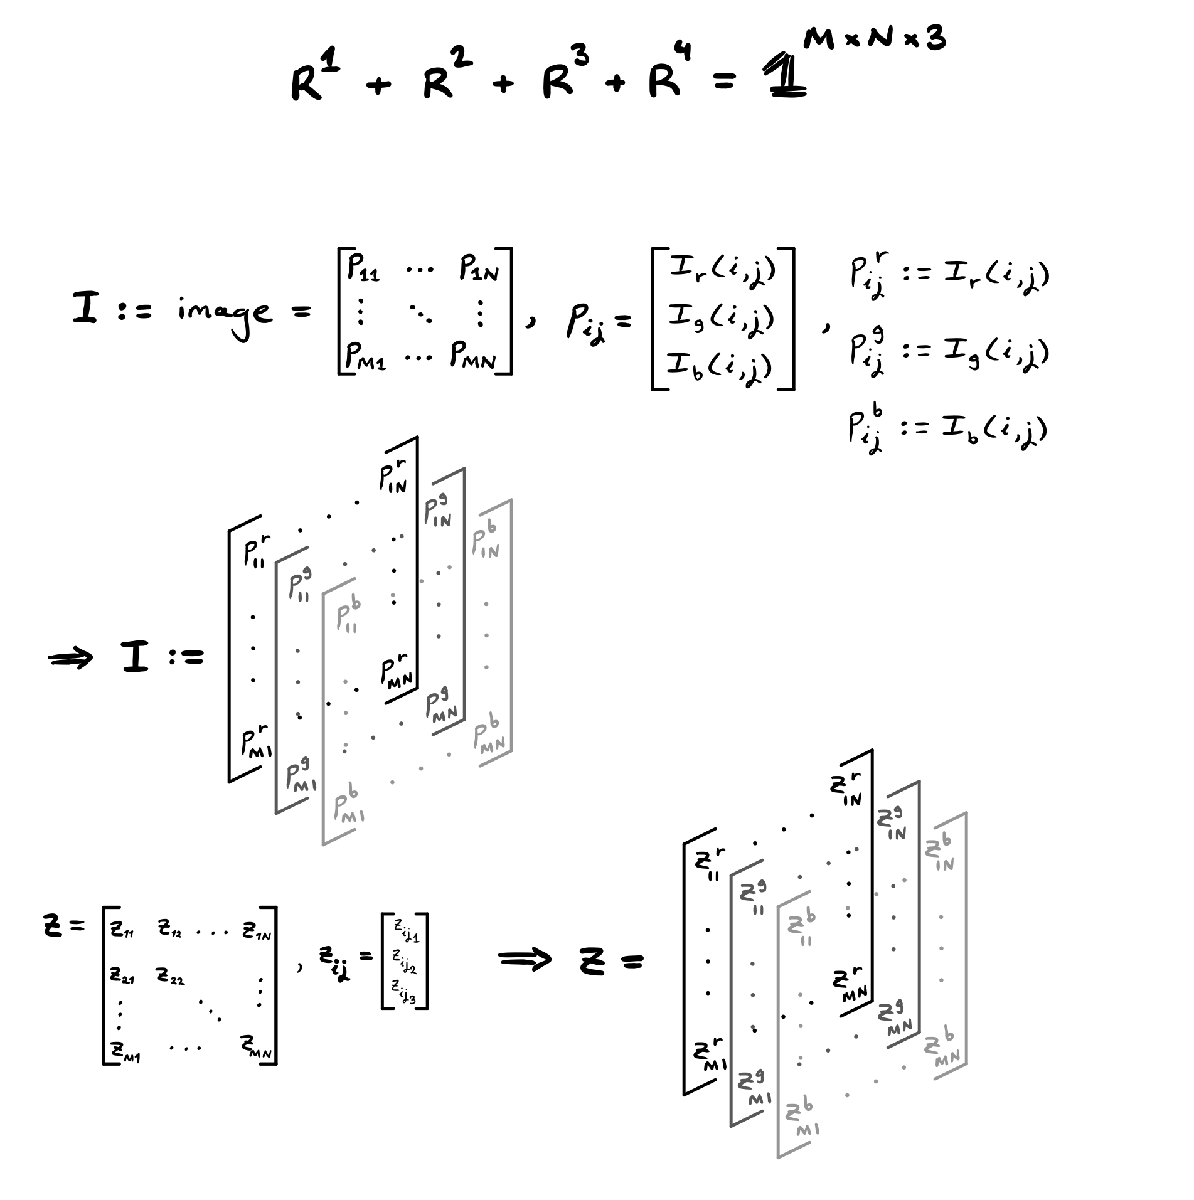

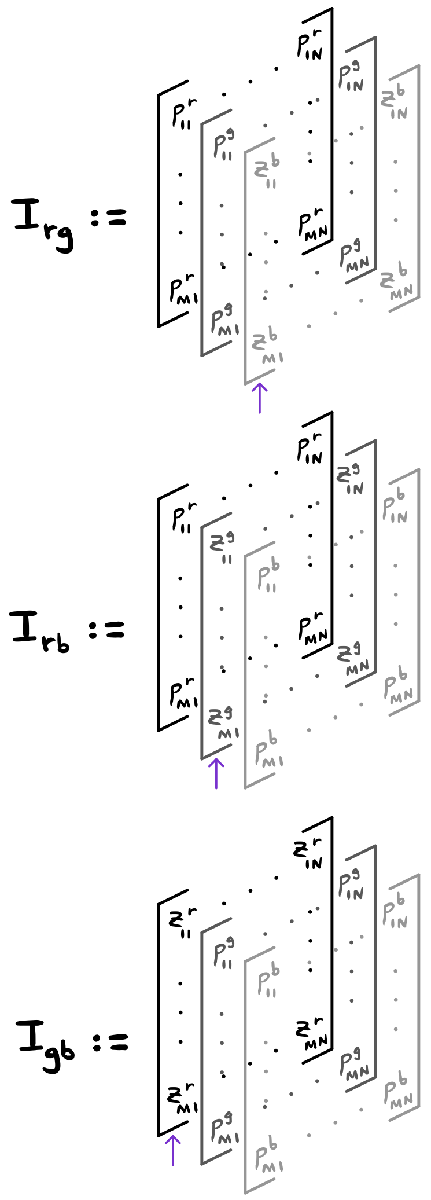

With the constructed $R^1,R^2,R^3,R^4$ (i.e. `r1`, `r2`, `r3`, `r4` in the funtion's code) and $I_{rg},I_{rb},I_{gb}$, element-wise matrix multiplication is used to compute the final resulting distorted/noisy image.